# Color transfer between images

## Color transfer will transfer the color tone from the source image to the target image.

Step 1: Input images are a source and a target image.  Display both images.

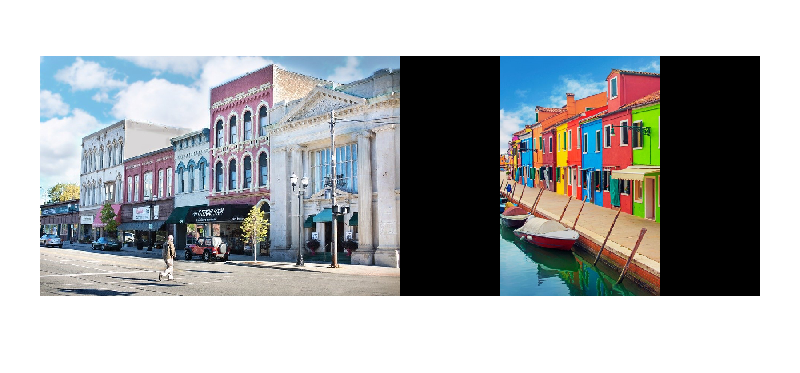

% 6388014 Waris Damkham.
imgsrc = imread('city_block1.png');
imgtarget = imread('colorful_town1.png');
orisrc = imgsrc;
oritarget = imgtarget;
[Msrc,Nsrc] = size(imgsrc);
[Mtarget,Ntarget,Dtarget] = size(imgtarget);
montage({imgsrc,imgtarget});

Step 2: Convert RGB to lαβ color space.  Images have size [m n 3].  You can use function "reshape" to change the size to [m*n  3]. So that we can multiply with other matrices.  

RGB2LMS = [0.3811 0.5783 0.0402 ; 0.1967 0.7244 0.0782 ; 0.0241 0.1288 0.8444];
LMS2LAB = [(1/sqrt(3)) 0 0; 0 (1/sqrt(6)) 0 ; 0 0 (1/sqrt(2))]*[1 1 1 ; 1 1 -2 ; 1 -1 0];
imgsrc = reshape(im2double(imgsrc),[],3);
imgtarget = reshape(im2double(imgtarget),[],3);
imgsrc = max(imgsrc,1/255);
imgtarget = max(imgtarget,1/255);
imgsrc = RGB2LMS*imgsrc';
imgtarget = RGB2LMS*imgtarget';
imgsrc = log10(imgsrc);
imgtarget = log10(imgtarget);
imgsrc = LMS2LAB*imgsrc;
imgtarget = LMS2LAB*imgtarget;

Step 3: Compute the mean and standard deviation of each of the lαβ channels for the source and target images.

imgsrc_mean = mean(imgsrc,2);
imgtarget_mean = mean(imgtarget,2);
imgsrc_std = std(imgsrc,0,2);
imgtarget_std = std(imgtarget,0,2);

Step 4: Subtract the mean of the lαβ channels of the target image from target channels.

imgtarget = imgtarget - imgtarget_mean;

Step 5: Scale the target channels by the ratio of the standard deviation of the source divided by the standard deviation of the target, multiplied by the target channels.

imgtarget = (imgsrc_std./imgtarget_std).*imgtarget;

Step 6: Add in the means of the lαβ channels for the source.

imgtarget = imgtarget + imgsrc_mean;

Step 7: Convert lαβ back to RGB color space.

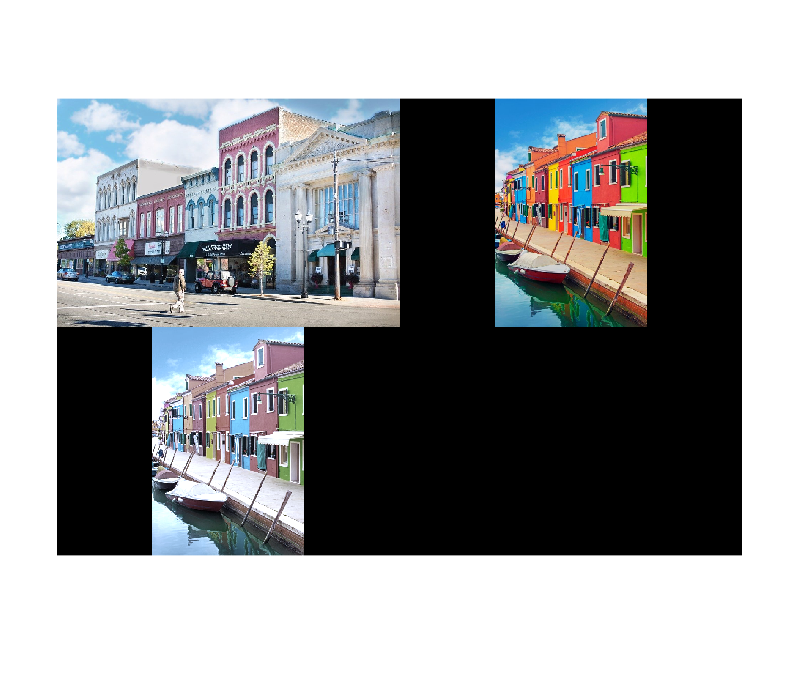

LAB2LMS = [1 1 1; 1 1 -1; 1 -2 0]* [(sqrt(3)/3) 0 0; 0 (sqrt(6)/6) 0; 0 0 (sqrt(2)/2)];
LMS2RGB = [4.4679 -3.5873 0.1193; -1.2186 2.3809 -0.1624; 0.0497 -0.2439 1.2045];
imgtarget = LAB2LMS*imgtarget;
imgtarget = 10.^imgtarget;
imgtarget = (LMS2RGB*imgtarget)';
img_result = reshape(imgtarget(:),Mtarget,Ntarget,[]);
montage({orisrc,oritarget,img_result});